close all, clear all, clc

## **HW03, 02**

Given that, as just 1 calculation is possible from the model because of expensiveness, so, that calculated value is going to be SRQ from the model

The inlet conditions are-

P_o1 = 7.15;        % outlet pressure; MPa
T_av1 = 284.9;      % Avg temp; dC
m_fl1 = 20.3;       % mass inflow; t/hr
wd = 132.5;         % assembly width; mm
rd = 8.0;           % assembly radius; mm
cf = 1.0;           % friction coeff
ksp = 1.2;          % spacer-grid p-loss factor

Then, the Random Variable SRQ from the model is-

mu_y = bfbt_T(P_o1, T_av1, m_fl1, wd, rd, cf, ksp)      % KPa

mu_y = 3.3245

Now, the experimenal pressure drop are follows

DP_e = [3.12, 3.00, 2.88, 3.18, 3.17, 2.92, 3.23, 2.84, 3.19, 3.15];        % KPa

Form the experimental sample, we get the follows-

N = size(DP_e, 2)           % sample size

N = 10

y_b_e = mean(DP_e)          % sample mean; KPa

y_b_e = 3.0680

sg_b_e = std(DP_e)          % sample STD; KPa

sg_b_e = 0.1443

Then, the Estimated Error in the computational model-

$\tilde{E} =\mu_y -{\bar{y} }_e$; 

E_b = mu_y - y_b_e          % KPa

E_b = 0.2565

The true mean of the population would be

$E=\mu_y -\mu_e \;$;         $\mu_e$ = true mean of the population

for a Validation Metric at 95% confidence level, we have 


$$\textrm{CL}=100\left(1-a\right)$$


CL = 95;            % confidence level
a = 1 - CL/100

a = 0.0500

Then, the validation metric would be presented by the following range-

$\tilde{y} -t_{\frac{a}{2},\nu \;} \frac{\;\bar{\sigma_e } }{\;\sqrt{\;N}}<\mu_e <\tilde{y} +t_{\frac{a}{2},\nu \;} \frac{\;\bar{\sigma_e } }{\;\sqrt{\;N}}$; hence-


$$\mu_y -\left(\tilde{y} -t_{\frac{a}{2},\nu \;} \frac{\;\bar{\sigma_e } }{\;\sqrt{\;N}}\right)>\left(\mu_y -\mu_e \right)>\mu_y -\left(\tilde{y} +t_{\frac{a}{2},\nu \;} \frac{\;\bar{\sigma_e } }{\;\sqrt{\;N}}\right)$$


Which renders our validation metric-


$$\tilde{E} -t_{\frac{a}{2},\nu \;} \frac{\;\bar{\sigma_e } }{\;\sqrt{N}}<E<\tilde{E} +t_{\frac{a}{2},\nu \;} \frac{\;\bar{\sigma_e } }{\;\sqrt{N}}\;$$


Now, let's define a normalize std like this-


$$\bar{\;\sigma_t } =\frac{\bar{\;\sigma_e } }{\sqrt{\;N}}$$


sg_b_t = sg_b_e/sqrt(N)     % STD, normalized; KPa

sg_b_t = 0.0456

nu = N - 1                  % DOF for the sample

nu = 9

Hence, we get the following range for validation-


$$\tilde{E} -t_{0\ldotp 025,9\;} \bar{\sigma_t } <E<\tilde{E} +t_{0\ldotp 025,9\;} \bar{\sigma_t } \;$$


Now, from the t-score table, we get for  $\nu =9;\frac{\alpha }{2}=0\ldotp 025$, t-value to be-

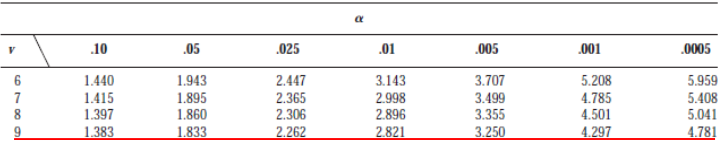

t = 2.262;

Then, let's calculate the upper and lower bound

E_lw = E_b - t*sg_b_t       % lower bound; KPa

E_lw = 0.1533

E_up = E_b + t*sg_b_t       % upper bound; KPa

E_up = 0.3597

So, the validation metric could be represented by-

${\tilde{E} }_{\textrm{lw}} <E<{\tilde{E} }_{\textrm{up}}$        (Ans)

- where, upper and lower bounds are values shown above.